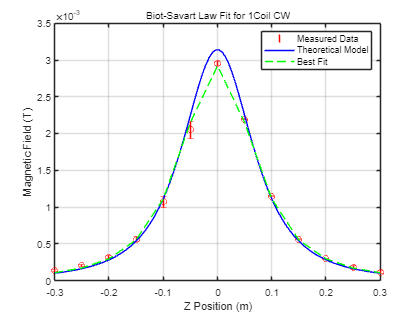

Best-fit parameters for 1Coil CW:
I = 0.976 A ± 0.012 A
R = 0.105 m ± 0.002 m



clc;
clear all;
close all;

% Define the Excel file name
excelFileName = 'BS_Data.xlsx';

%% 1. 1 Coil CW

% Sheet name for this setup
sheetName = '1Coil CW';

% Import data
data = xlsread(excelFileName, sheetName);

% Extract z_positions, measured_B , and error
z_positions = data(:, 1);
measured_B1 = data(:, 5);
error1 = data(:, 6);      

% Coil configuration
coilConfig(1).position = 0;
coilConfig(1).N_turns = 500;
coilConfig(1).direction = 1; 

% Analysis and plotting
analyzeAndPlot(z_positions, measured_B1, error1, coilConfig, sheetName);

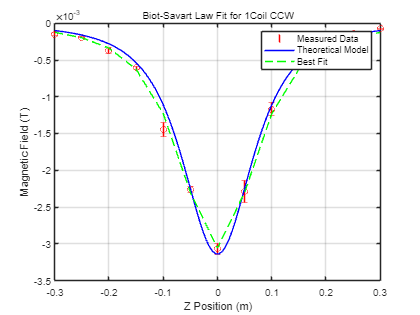

Best-fit parameters for 1Coil CCW:
I = 1.066 A ± 0.023 A
R = 0.109 m ± 0.003 m




%% 2. 1 COil CCCw

sheetName = '1Coil CCW';

% Import data
data = xlsread(excelFileName, sheetName);

% Extract data
z_positions = data(:, 1);
measured_B2 = data(:, 5);
error2 = data(:, 6);

% Coil configuration
coilConfig(1).position = 0;
coilConfig(1).N_turns = 500;
coilConfig(1).direction = -1; 

% Analysis and plotting
analyzeAndPlot(z_positions, measured_B2, error2, coilConfig, sheetName);

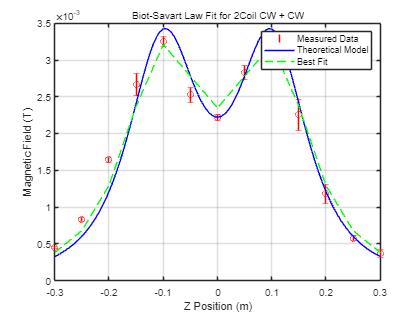

Best-fit parameters for 2Coil CW + CW:
I = 1.013 A ± 0.029 A
R = 0.110 m ± 0.006 m




%% 3. 2 Coil CW + CW

sheetName = '2Coil CW + CW';

% Import data
data = xlsread(excelFileName, sheetName);

% Extract data
z_positions = data(:, 1);
measured_B3 = data(:, 5);
error3 = data(:, 6);

% Coil configuration
L = 0.1; 
coilConfig(1).position = -L;
coilConfig(1).N_turns = 500;
coilConfig(1).direction = 1; 

coilConfig(2).position = L;
coilConfig(2).N_turns = 500;
coilConfig(2).direction = 1; 

% Analysis and plotting
analyzeAndPlot(z_positions, measured_B3, error3, coilConfig, sheetName);

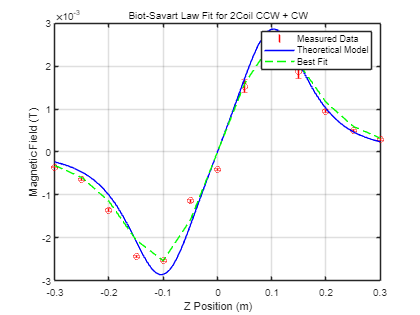

Best-fit parameters for 2Coil CCW + CW:
I = 1.100 A ± 0.104 A
R = 0.118 m ± 0.010 m




%% 4.2Coil CCW + CW

sheetName = '2Coil CW + CCW'; 

% Import data
data = xlsread(excelFileName, sheetName);

% Extract data
z_positions = data(:, 1);
measured_B4 = data(:, 5);
error4 = data(:, 6);

% Coil configuration 
L = 0.1;
coilConfig(1).position = -L;
coilConfig(1).N_turns = 500;
coilConfig(1).direction = -1;

coilConfig(2).position = L;
coilConfig(2).N_turns = 500;
coilConfig(2).direction = 1;

% Analysis and plotting
analyzeAndPlot(z_positions, measured_B4, error4, coilConfig, '2Coil CCW + CW');


%% 5. 3Coil CW + CW + CW

sheetName = '3Coil CW +CW + CW';

% Import data
data = xlsread(excelFileName, sheetName);

% Extract data
z_positions = data(:, 1); 
measured_B5 = data(:, 5);
error5 = data(:, 6);

% Coil configuration 
L = 0.2;
coilConfig(1).position = -L;
coilConfig(1).N_turns = 500;
coilConfig(1).direction = 1; 

coilConfig(2).position = 0; 
coilConfig(2).N_turns = 500;
coilConfig(2).direction = 1;

coilConfig(3).position = L; 
coilConfig(3).N_turns = 500;
coilConfig(3).direction = 1; 

% Analysis and plotting
analyzeAndPlot(z_positions, measured_B5, error5, coilConfig, sheetName);

Best-fit parameters for 3Coil CW +CW + CW:
I = 0.995 A ± 0.018 A
R = 0.101 m ± 0.004 m



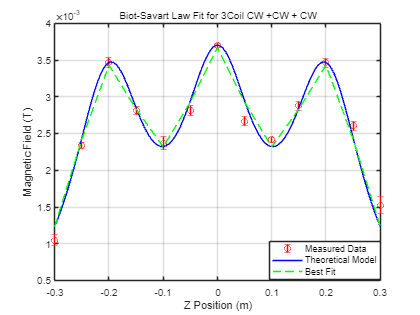


legend("Position", [0.64286,0.11508,0.2625,0.11905])

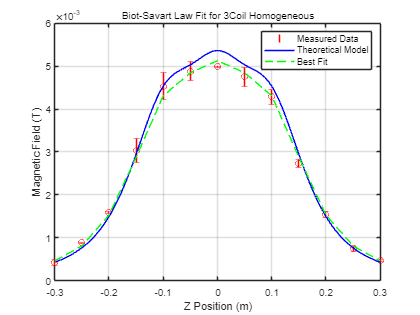

Best-fit parameters for 3Coil Homogeneous:
I = 0.979 A ± 0.013 A
R = 0.107 m ± 0.004 m




%% 6. 3Coil Homogeneous

sheetName = '3Coil Homogeneous';

% Import data
data = xlsread(excelFileName, sheetName);

% Extract data
z_positions = data(:, 1);
measured_B6 = data(:, 5);
error6 = data(:, 6);

% Coil configuration
L = 0.1;
coilConfig(1).position = -L;
coilConfig(1).N_turns = 500;
coilConfig(1).direction = 1; % CW

coilConfig(2).position = 0;
coilConfig(2).N_turns = 500;
coilConfig(2).direction = 1; % CW

coilConfig(3).position = L;
coilConfig(3).N_turns = 500;
coilConfig(3).direction = 1; % CW

% Analysis and plotting
analyzeAndPlot(z_positions, measured_B6, error6, coilConfig, sheetName);

%% Function Definitions

% Function to analyze data and plot results

function analyzeAndPlot(z_positions, measured_B, error, coilConfig, sheetName)
    % Plot the measured data with error bars
    figure('Name', sheetName, 'NumberTitle', 'off');
    errorbar(z_positions, measured_B, error, 'ro');
    xlabel('Position along z-axis (m)');
    ylabel('Magnetic Field (T)');
    legend('Measured Magnetic Field Data');
    grid on;
    box on;
    hold on;
    
    % Initial guesses for current and radius
    initial_I = 1.0; 
    initial_R = 0.1; 
    initialGuess = [initial_I, initial_R]; 
    
    % Theoretical model using initial guesses
    theoretical_z = linspace(min(z_positions), max(z_positions), 100);
    theory_B = biotsavartequation(initialGuess, theoretical_z, coilConfig);
    
    % Plot the theoretical model
    plot(theoretical_z, theory_B, 'b-');
    
    % Prepare the model function for fitting
    mdl = @(params, z) biotsavartequation(params, z, coilConfig);
    
    % Perform the nonlinear fit 
    BiotSavartFit = fitnlm(z_positions, measured_B, mdl, initialGuess);
    
    % Extract the best-fit parameters
    best_fit_I = BiotSavartFit.Coefficients.Estimate(1);
    best_fit_R = BiotSavartFit.Coefficients.Estimate(2);
    I_error = BiotSavartFit.Coefficients.SE(1);
    R_error = BiotSavartFit.Coefficients.SE(2);
    
    % Generate the fit data using the best-fit parameters
    B_fit = biotsavartequation([best_fit_I, best_fit_R], z_positions, coilConfig);
    
    % Plot the best-fit data
    plot(z_positions, B_fit, 'g--');
    xlabel('Z Position (m)');
    ylabel('Magnetic Field (T)');
    legend('Measured Data', 'Theoretical Model', 'Best Fit');
    title(['Biot-Savart Law Fit for ', strrep(sheetName, '_', '\_')], 'FontSize', 10, 'FontWeight', 'normal');
    hold off;
    
    % Display the best-fit parameters
    fprintf('Best-fit parameters for %s:\n', sheetName);
    fprintf('I = %.3f A ± %.3f A\n', best_fit_I, I_error);
    fprintf('R = %.3f m ± %.3f m\n\n', best_fit_R, R_error);
end

% Biot-Savart Law function
function [B_field] = biotsavartequation(params, z, coilConfig)
    I = params(1); 
    R = params(2); 
    mu_0 = 4 * pi * 1e-7; 
    
    B_field = zeros(size(z));
    
    % Sum the magnetic field contributions from each coil
    for k = 1:length(coilConfig)
        N = coilConfig(k).N_turns;
        z0 = coilConfig(k).position;
        dir = coilConfig(k).direction;
        % Shift z positions relative to the coil's position
        z_shifted = z - z0;
        % Biot-Savart Law for the magnetic field along the z-axis of a single coil
        B_coil = dir * (mu_0 / 2) * (I * N * R^2) ./ (R^2 + z_shifted.^2).^(3/2);
        B_field = B_field + B_coil; % Sum contributions
    end
end